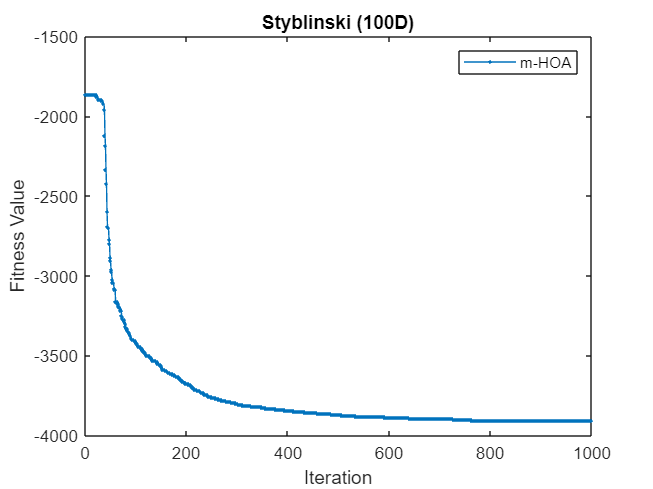

%%RUN THIS TO EXECUTE Modified-HOA
[VarMin, VarMax, nVar] = HOA_Final_InitialData;
z = @HOA_Final_Functions;

%Number of runs to find average performance, standard deviation, etc.
NRuns = 10;
%Population Size
nHorse = 50;
%No. of members in each neighbourhood
ns = 5;
%Total Number of iterations in each run
MaxIt = 1000;

empty_GlobalBestmHOA.Position=[];
empty_GlobalBestmHOA.Cost=[];
GlobalBestmHOA=repmat(empty_GlobalBestmHOA,NRuns,1);

BestCostmHOA = zeros(NRuns, MaxIt);

for i = 1:NRuns
   [BestCostmHOA(i,:), GlobalBestmHOA(i)] = HOA_Final(z,nVar,VarMin, VarMax, nHorse, ns, MaxIt);
%    disp([ ' m-HOA: Best Position = '  num2str(GlobalBestmHOA(i).Position)])
%    disp([ ' m-HOA: Best Cost = '  num2str(GlobalBestmHOA(i).Cost)])
%    disp([ ' Time = '  num2str(toc)])
end

mHOAIterData = mean(BestCostmHOA, 1);

x = [1 : 1: 1000];
y = mHOAIterData;
plot(x, y,'.-'), legend('m-HOA')
xlabel('Iteration');
ylabel('Fitness Value');
title('Styblinski (100D)');


% T = struct2table(GlobalBestmHOA)
% filename = 'Modified_HOA Styblinski 100 Var.xlsx';
% writetable(T,filename);